% ALL THE HELPER FUNCTIONS

function dstate_dt = dynamics(state, forces, params)
    % Unpack parameters and state for clarity
    mq = params.mq;
    mb = params.mb;
    ms = params.ms;
    L = params.L;
    Ixx = params.Ixx;
    g = params.g;
    r = params.r;
    
    y = state(1);
    z = state(2);
    phi = state(3);
    theta = state(4);
    y_d = state(5);
    z_d = state(6);
    phi_d = state(7);
    theta_d = state(8);

    Fl = forces(1);
    Fr = forces(2);
  
    Ip = ms*L^2/3+mb*L^2;
    Lcg = L*(ms/2+mb)/(ms+mb);
    
    % A*x_dd = B
    
    % Dynamics derived from the pdf
    A = [ms+mb+mq 0 (ms+mb)*Lcg*cos(phi+theta) (ms+mb)*Lcg*cos(phi+theta);
        0 ms+mb+mq (ms+mb)*Lcg*sin(phi+theta) (ms+mb)*Lcg*sin(phi+theta);
        Lcg*cos(phi+theta)*(ms+mb) Lcg*sin(phi+theta)*(ms+mb) Ip Ip;
        0 0 Ixx 0];
    
    B = [-(Fl+Fr)*sin(phi)+(ms+mb)*Lcg*sin(phi+theta)*(phi_d+theta_d)^2 ;
        (Fl+Fr)*cos(phi)-(ms+mb)*Lcg*cos(phi+theta)*(phi_d+theta_d)^2-g*(ms+mb+mq) ;
        -g*Lcg*(ms+mb)*sin(phi+theta) ; 
        (Fr-Fl)*r];
    
    state_dd = A\B;

    dstate_dt = [y_d ; z_d ;phi_d ;theta_d; state_dd];
end

function [time, state_history] = run_simulation(initial_state, Fl_history, Fr_history, T, N, params)
    dt = T / N;
    time = linspace(0, T, N+1)';
    state_history = zeros(N+1, length(initial_state));
    state_history(1, :) = initial_state;
    
    current_state = initial_state(:); % Ensure it's a column vector
    
    for k = 1:N
        forces = [Fl_history(k); Fr_history(k)];
        
        dstate_dt = dynamics(current_state, forces, params); 
        
        % Simple Euler integration step
        current_state = current_state + dstate_dt * dt;
        state_history(k+1, :) = current_state';
    end
end

function [J, c, ceq] = objectiveAndConstraints(x, initial_state, target_state, T, N, params)
    forces = reshape(x, [2, N])'; % Reshape to an N x 2 matrix
    Fl_history = forces(:, 1);
    Fr_history = forces(:, 2);

    % 2. Run the simulation
    [~, state_history] = run_simulation(initial_state, Fl_history, Fr_history, T, N, params);

    % 3. Calculate Objective Function (J)
    % Minimize the sum of the control effort squared over the trajectory.
    dt = T / N;

    % Cost without the final equality constraint -> encourages angle
    % (doesn't work)
    % J = sum(sqrt((state_history(:,4).^2)-pi).^2) * dt;

    % Cost with only actuation history
    J = sum(Fl_history.^2 + Fr_history.^2) * dt;

    % Cost with actuation history + changes in actuations
    J = J+ sum((Fl_history-[Fl_history(1); Fl_history(1:end-1)]).^2 + (Fr_history-[Fr_history(1) ;Fr_history(1:end-1)]).^2) * dt;

    % 4. Calculate Inequality Constraints (c <= 0)
    z_history = state_history(:, 2); 
    z_initial = initial_state(2);
    z_upper_bound = z_initial * 1.10;
    z_lower_bound = z_initial * 0.90;

    phi_history = state_history(:,3);
    phi_upper_bound = pi/6;
    phi_lower_bound = -pi/6;

    y_history = state_history(:,1);
    y_upper_bound = 0.2;
    y_lower_bound = -0.2;

    % fmincon requires c(x) <= 0
    c1 = z_history - z_upper_bound;
    c2 = z_lower_bound - z_history;
    c3 = phi_history - phi_upper_bound;
    c4 = phi_lower_bound - phi_history;
    c5 = y_history - y_upper_bound;
    c6 = y_lower_bound - y_history;
    c = [c1; c2; c3; c4; c5; c6];

    % This hard constraint is now solely responsible for reaching the target.
    final_state = state_history(end, :);
    ceq = final_state(:) - target_state(:);
end

function [c,ceq] = constraint_wrapper(x, initial_state, target_state, T, N, params)
    [~, c, ceq] = objectiveAndConstraints(x, initial_state, target_state, T, N, params);
    % ceq = [];
end

function J = objective_wrapper(x, initial_state, target_state, T, N, params)
    [J, ~, ~] = objectiveAndConstraints(x, initial_state, target_state, T, N, params);
end

function [Fl_guess, Fr_guess] = getInitialGuess(params,T,N)
    % Initial Guess (crucial for convergence!)
    % A good guess is constant thrust to counteract gravity, then small random perturbations
    hover_force = ((params.ms+params.mb+params.mq) * params.g) / 2;
    t_guess = linspace(0, T, N); % Time vaector for the guess
    
    % Create a sinusoidal nudge force    
    nudge_amplitude = hover_force * 0.001; 
    nudge_freq = sqrt(params.g/params.L)*1; 
    
    Fl_guess = hover_force*ones([N,1]);
    Fr_guess = hover_force*ones([N,1]);

    % Chirp & increasing amplitude to encourage quadcopter to get back to
    % middle and not just drift off to infinity to one side.
    Fl_guess = hover_force + nudge_amplitude*log10(t_guess+1) .* chirp(t_guess, nudge_freq*1.8/(2*pi),3,nudge_freq*0.3/(2*pi));
    Fr_guess = hover_force - nudge_amplitude*log10(t_guess+1) .* chirp(t_guess, nudge_freq*1.8/(2*pi),3,nudge_freq*0.3/(2*pi));

    [time, state_guess] = run_simulation(initial_state, Fl_guess, Fr_guess, T, N, params);

    figure;
    plot(time(1:length(Fl_guess)),Fl_guess',time(1:length(Fr_guess)),Fr_guess')
    title("Initial Guess Forces")
    xlabel("Time (s)")
    ylabel("Force (N)")
    legend("Fl","Fr")

    figure;
    plot(time,state_guess(:,3))
    title("Initial Guess Phi Trajectory")
    xlabel("Time (s)")
    ylabel("Phi (rad)")

    figure;
    hold on
    plot(state_guess(:,1),state_guess(:,2))
    title("Initial Guess Trajectory")
    xlabel("y (m)")
    ylabel("z (m)")
    hold off
end

clear; clc; close all;

function [Fl_opt,Fr_opt, state_opt, successful] = optimization(Fl_guess, Fr_guess, params)

    T = 4.0; % Total maneuver time in seconds
    N = 100;  % Number of discretization steps
    
    y_initial = 0;
    z_initial = 1.0;
    initial_state = [y_initial, z_initial, 0, 0, 0, 0, 0, 0];
    target_state  = [y_initial, z_initial, 0, deg2rad(178), 0, 0, 0, 0.01]; % 180 deg = pi radians
    
    n_vars = 2 * N;
    
    % Bounds
    max_force = 0.3; % Newtons
    lb = zeros(n_vars, 1);
    ub = max_force * ones(n_vars, 1);

    x0 = zeros(n_vars, 1);
    x0(1:2:end) = Fl_guess; % Odd elements are Fl
    x0(2:2:end) = Fr_guess; % Even elements are Fr
    
    fprintf('Running fmincon...\n');
    options = optimoptions('fmincon', 'Display', 'iter', 'Algorithm', 'sqp', ...
                           'MaxFunctionEvaluations', 750000, 'MaxIterations', 1000, ...
                           'ConstraintTolerance', 1e-4, 'StepTolerance', 1e-8);
    
    objFun = @(x) objective_wrapper(x, initial_state, target_state, T, N, params);
    nonlconFun = @(x)  constraint_wrapper(x, initial_state, target_state, T, N, params);
    
    [x_optimal, fval, exitflag, output] = fmincon(objFun, x0, [], [], [], [], lb, ub, nonlconFun, options);
    
    if exitflag > 0
        fprintf('Optimization successful!\n');
        successful = true;
    else
        fprintf('Optimization failed. Exit flag: %d\n', exitflag);
        successful = false;
    end
        
    % Reshape optimal forces
    forces_opt = reshape(x_optimal, [2, N])';
    Fl_opt = forces_opt(:, 1);
    Fr_opt = forces_opt(:, 2);
    
    % Rerun simulation with optimal controls to get the final trajectory
    [time, state_opt] = run_simulation(initial_state, Fl_opt, Fr_opt, T, N, params);

    % Plotting
    figure;
    
    % Plot States
    subplot(2,1,1);
    plot(time, rad2deg(state_opt(:,4)), 'b-', 'LineWidth', 1);
    hold on;
    plot(time(end), rad2deg(target_state(4)), 'rx', 'MarkerSize', 10, 'LineWidth', 1);
    title('State Trajectories');
    ylabel('Angle (deg)');
    grid on;
    
    % Plot Controls
    subplot(2,1,2);
    stairs(time(1:end-1), Fl_opt, 'r-', 'LineWidth', 1);
    hold on;
    stairs(time(1:end-1), Fr_opt, 'g-', 'LineWidth', 1);
    title('Control Inputs (Forces)');
    xlabel('Time (s)');
    ylabel('Force (N)');
    legend('Fl (Left)', 'Fr (Right)');
    grid on;
    ylim([0, max_force * 1.1]);    
    hold off

    figure;

    % Plot Trajectory
    subplot(2,1,1);
    hold on
    plot(state_opt(:,1),state_opt(:,2))
    title("Optimized Trajectory")
    xlim([-0.1,0.1])
    ylim([0.8,1.25])
    xlabel("y (m)")
    ylabel("z (m)")
    
    % Plot Y Trajectory over time
    subplot(2,1,2);
    hold on
    plot(time,state_opt(:,1))
    title("Y Displacement over Time")
    xlabel("Time (s)")
    ylabel("Y Displacement (m)")
    hold off
end


Running fmincon...
 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order  
                                                                       step    optimality
    0         201    3.332443e-01     3.412e-05     1.000e+00     0.000e+00     1.803e-02  
    1         437    3.332443e-01     3.412e-05     3.788e-06     5.181e-08     1.803e-02  
    2         674    3.332443e-01     3.412e-05     2.652e-06     5.965e-08     1.803e-02  
    3         712    3.332443e-01     3.412e-05     1.299e-06     3.800e-08     1.697e-03  

Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satis

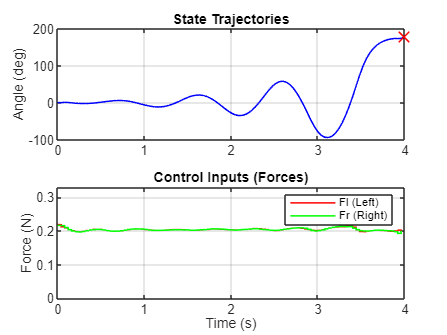

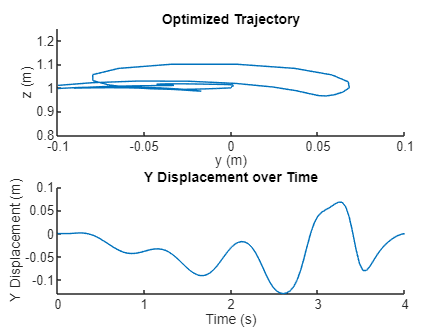

FL_opt = load('data/fl_opt_178deg.mat').Fl_opt;
FR_opt = load('data/fr_opt_178deg.mat').Fr_opt;

params.mq = 0.029; % kg
params.mb = 0.01; % kg
params.ms = 0.0025; % kg
params.Ixx = 6.410179e-06; % kg m2
params.g = 9.81; % kg/m2
params.r = 0.05665/2; % m

for length=0.30:0.01:0.30
    params.L = length; % m
    [fl_opt,fr_opt, state_opt, successful] = optimization(FL_opt(:,end),FR_opt(:,end), params);
    if (~successful)
        break
    end
    FL_opt = [FL_opt , fl_opt];
    FR_opt = [FR_opt, fr_opt];
end


FL_opt

FL_opt =     0.2189    0.2189
    0.2124    0.2124
    0.2091    0.2091
    0.2040    0.2040
    0.2005    0.2005
    0.1980    0.1980
    0.1973    0.1973
    0.1986    0.1986
    0.2010    0.2010
    0.2030    0.2030


FR_opt

FR_opt =     0.2166    0.2166
    0.2157    0.2157
    0.2101    0.2101
    0.2040    0.2040
    0.1998    0.1998
    0.1976    0.1976
    0.1968    0.1968
    0.1983    0.1983
    0.2005    0.2005
    0.2028    0.2028
